% Define the number of agents
N = 5;

% Define the maximum X, Y
xMax = 1;
yMax = 1;

% Length of one time step
dt = 0.01;

% How long the simulation will run
T = 10;

% Maximum acceleration of an agent
aMax = 0.3;

% Calculate the number of time steps
numSteps = floor(T / dt)

numSteps = 1000


% Initialize the positions array
agents = zeros(N, 2, numSteps);

% Initialize the random positions of agents at time t = 0
agents(:,:,1) = rand(N, 2) .* [xMax, yMax];
agents_dot = zeros(5,2);

Laplacian for a single path

% --------------------------------
% define the adjacency matrix
A = [[0, 1, 0, 0, 0];
     [1, 0, 1, 0, 0];
     [0, 0, 0, 0, 1];
     [0, 1, 2, 0, 1];
     [0, 0, 3, 1, 0]];
% define the laplacian matrix


D = diag(sum(A,2));
L = D-A;

c = null(L');
c = c/sum(c);
consensus = c'*agents(:,:,1)

consensus =     0.5845    0.2166


in = sum(A, 2)';
out = sum(A, 1);
deg = in + out;
% --------------------------------

The Simulation

for t = 2*dt:dt:T
    idx = cast(t/dt, "uint32");
    x = agents(:,1,idx-1);
    y = agents(:,2,idx-1);
    deltadot = (agents_dot-[L*x, L*y]);
    agentsdotdot = deltadot.*min(1, aMax./vecnorm(deltadot,2,2));
    agents_dot = agents_dot - agentsdotdot*dt;
    x_updated = x - agents_dot(:,1)*dt;
    y_updated = y - agents_dot(:,2)*dt;
    agents(1:N, 1, idx) = x_updated;
    agents(1:N, 2, idx) = y_updated;
end 

% Extract the positions of agents from the "agents" array
initialPositions = squeeze(agents(:, :, 1));
finalPositions = squeeze(agents(:, :, end));

% Plot the initial positions
scatter(initialPositions(:, 1), initialPositions(:, 2), 'ro', 'MarkerFaceColor', 'r');
hold on;

% Plot the final positions
scatter(finalPositions(:, 1), finalPositions(:, 2), 'go', 'MarkerFaceColor', 'g');

% Plot the trajectories
for agent = 1:N
    trajectory = squeeze(agents(agent, :, :))';
    plot(trajectory(:, 1), trajectory(:, 2));
end

mean(agents(:,:,numSteps), 1)

ans =     0.6139    0.2294


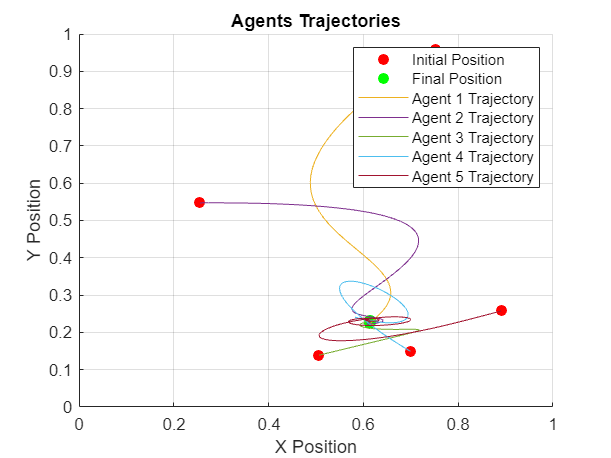


hold off;
xlabel('X Position');
ylabel('Y Position');
title('Agents Trajectories');
legend('Initial Position', 'Final Position', 'Agent 1 Trajectory', 'Agent 2 Trajectory', 'Agent 3 Trajectory', 'Agent 4 Trajectory', 'Agent 5 Trajectory');
grid on;
axis([0 xMax 0 yMax]);